# Optimization of the multiple feeding trajectory

**Manipulated variables**

- `u1 = Q_Glc [L/h]`: feed rate of glucose

- `u2 = Q_Gln [L/h]`: feed rate of glutamine

**Measured disturbance**

- `none`

**State variables**

- `x1 = V [L]`: liquid volume in the reactor

- `x2 = Xv [cell/L]`: viable cell density

- `x3 = Xt [cell/L]`: total cell density 

- `x4 = Gl`c` [mM]`: Glucose concentration

- `x5 = Gln [mM]`: Glutamine concentration

- `x6 = Lac [mM]`: Lactate concentration

- `x7 = Amm [mM]`: Ammonia concentration

- `x8 = mAb_ext [mg/L]`: extracellular mAb concentration

- `x9 = mRNA_Hc [molecule/cell]:` Intracellular amount of mRNA for heavy chains

- `x10 = mRNA_Lc [molecule/cell]` `:` Intracellular amount of mRNA for light chains

- `x11 = Hc [molecule/cell]:` Intracellular amount of heavy chains

- `x12 = Lc [molecule/cell]:` Intracellular amount of light chains

- `x13 = Hc2 [molecule/cell]:` Intracellular amount of heavy chain dimers

- `x14 = Hc2Lc [molecule/cell]:` Intracellular amount of assemblies of heavy and light chains

- `x15 = mAb_ER [molecule/cell]:` mAb amount in the endoplasmic reticulum

- `x16 = mAb_gol [molecule/cell]:` mAb amount in the golgi apparatus

- `x17 = V_Glc [L]`: Cumulative feed volume of glucose 

- `x18 = V_Gln [L]`: Cumulative feed volume of glutamine 

**Output variables: the same as the state variables**

**The goal:** to maximize the final mAb mass (`x1(Tf)*x8(Tf)`). 

**Contraints:** 

- Upper bound on the fed volume of glucose feed medium (x`17`) 

- Upper bound on the fed volume of glutamine feed medium (x`18`) 

## Specify the initial states.

V0 = 0.2;       % [L]
Xv0 = 2E+8;     % [cell]
Xt0 = 2E+8;     % [cell]
Glc0 = 25.1;    % [mM]
Gln0 = 5.01;    % [mM]
Lac0 = 0;       % [mM]
Amm0 = 0;       % [mM]
mAb_ext0 = 100; % [mg/L]
mRNA_Hc0 = 0;
mRNA_Lc0 = 0;
Hc0 = 0;
Lc0 = 0;
Hc2_0 = 0;
Hc2Lc_0 = 0;
mAb_ER0 = 0;
mAb_gol0 = 0;
V_Glc0 = 0;
V_Gln0 = 0;

x0 = [V0; Xv0; Xt0; Glc0; Gln0; Lac0; Amm0; mAb_ext0; ...
            mRNA_Hc0; mRNA_Lc0; Hc0; Lc0; Hc2_0; Hc2Lc_0; mAb_ER0; mAb_gol0; ...
            V_Glc0; V_Gln0 ...
     ];

Specify the nominal inputs.

u0 = zeros(2,1);

## Design nonlinear MPC with the true model

Create a nonlinear MPC object with 18 states, 18 outputs, 2 manipulated variables, and NO measured disturbance.

nlmpcMFTrue = nlmpc(18,18,2); % nlpmc object

標準のコスト関数では、MV が OV より少ないため、既定で 1 つ以上の OV に 0 の重みが割り当てられます。


Given the expected bioprocess duration `Tf`, choose the controller sample time `Ts` and prediction horizon.

Tf = 168;   % [h] bioprocess duration
Ts = 12;    % [h] prediction model sample time
N = Tf/Ts;  % [step] prediction horizon
nlmpcMFTrue.Ts = Ts;
nlmpcMFTrue.PredictionHorizon = N;
% nlmpcobj.ControlHorizon = N;
nlmpcMFTrue.ControlHorizon = (24/Ts)*ones(7,1);
nlmpcMFTrue.Optimization.MVInterpolationOrder = 1;

### Specify the state function in the controller

The function converts the continuous-time model to discrete time using a multi-step Forward Euler integration formula.

STATEFCN = @multiFeedStateFcn;
nlmpcMFTrue.Model.StateFcn = @(x,u) discretizeStateFcn(x,u,Ts,STATEFCN);
nlmpcMFTrue.Model.OutputFcn = @(x,u) x;

% the nonlinear state function is for discrete-time models.
nlmpcMFTrue.Model.IsContinuousTime = false;

### Specify the bounds for input/output variables

% states
stateName = {'V','Xv','Xt','Glc','Gln','Lac','Amm','mAb_ext', ...
                'mRNA_Hc', 'mRNA_Lc', 'Hc', 'Lc', 'Hc2', 'Hc2Lc', ...
                'mAb_ER', 'mAb_gol', 'V_Glc', 'V_Gln',...
            };
stateUnit = {'L', 'cell/L', 'cell/L', 'mM', 'mM', 'mM', 'mM', 'mg/L', ...
                'molecule/cell', 'molecule/cell', 'molecule/cell', 'molecule/cell', ...
                'molecule/cell', 'molecule/cell', 'molecule/cell', 'molecule/cell', 'L', 'L' ...
            };
stateScaleFactor = [0.04 2.5E+9 2.5E+9 25 5 25 5 4000 ...
                        5E+6 5E+6 5E+6 5E+7 1E+6 1E+6 5E+7 2E+8 0.02 0.02...
                   ];

for stateIdx = 1:18
    nlmpcMFTrue.States(stateIdx).Name = stateName{stateIdx};
    nlmpcMFTrue.States(stateIdx).ScaleFactor = stateScaleFactor(stateIdx);
    nlmpcMFTrue.States(stateIdx).Units = stateUnit{stateIdx};
end

% manipulated variable
nlmpcMFTrue.MV(1).Name = 'Q_Glc';
nlmpcMFTrue.MV(1).ScaleFactor = 0.02/168;
nlmpcMFTrue.MV(1).Units = 'L/h';
nlmpcMFTrue.MV(1).Min = 0;
nlmpcMFTrue.MV(1).MinECR = 0;

nlmpcMFTrue.MV(2).Name = 'Q_Gln';
nlmpcMFTrue.MV(2).ScaleFactor = 0.02/168;
nlmpcMFTrue.MV(2).Units = 'L/h';
nlmpcMFTrue.MV(2).Min = 0;
nlmpcMFTrue.MV(2).MinECR = 0;

% output variables
for outputIdx = 1:18
    nlmpcMFTrue.OV(outputIdx).Name = nlmpcMFTrue.States(outputIdx).Name;
    nlmpcMFTrue.OV(outputIdx).ScaleFactor = nlmpcMFTrue.States(outputIdx).ScaleFactor;
    nlmpcMFTrue.OV(outputIdx).Units = nlmpcMFTrue.States(outputIdx).Units;
end

% Total feed limit
nlmpcMFTrue.OV(17).Max = 0.02;
nlmpcMFTrue.OV(17).MaxECR = 0.02;  % 0.02
nlmpcMFTrue.OV(18).Max = 0.02;
nlmpcMFTrue.OV(18).MaxECR = 0.02;  % 0.02

% weight for the slack variable e
rho_e = 1E-5; % 1E-5

### Specify the custom cost function

nlmpcMFTrue.Optimization.CustomCostFcn = @(X,U,e,data) 1/(X(end,8)*X(end,1)) + rho_e*e^2;
nlmpcMFTrue.Optimization.ReplaceStandardCost = true;

### Specify the solver option

nlmpcMFTrue.Optimization.SolverOptions.Display = 'iter-detailed';

### Validate the nlmpc object

validateFcns(nlmpcMFTrue, x0, u0);

Model.StateFcn is OK.
Model.OutputFcn is OK.
Optimization.CustomCostFcn is OK.
ユーザー指定のモデル、コストおよび制約関数の解析が完了しました。


## Off-line optimization of the feeding trajectory

Find the optimal trajectories for the manipulated variables such that mAb mass is maximized at the end of the process. To do so, use the `nlmpcmove` function.

### Specify the initial guess of manipulated variables

options = nlmpcmoveopt;
options.MV0 = (0.02/168)*[1,1];

### Start optimization

timenow = datestr(datetime('now'));
fprintf('Optimization started at %s',timenow);

Optimization started at 05-Dec-2022 23:37:18

tic
[~,~,Info_true] = nlmpcmove(nlmpcMFTrue,x0,u0,[],[],options)

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           1    5.000000e-02     2.216e+00     1.000e+00     0.000e+00     2.000e+00  
    1           3    3.297587e-02     1.182e+00     1.000e+00     6.363e+01     1.456e+04  
    2           5    2.153117e-02     1.745e+00     1.000e+00     1.217e+01     1.060e+02  
    3           7    2.225281e-02     7.000e-03     1.000e+00     3.502e+00     1.117e+01  
    4           9    2.226023e-02     1.673e-06     1.000e+00     2.116e-02     1.610e-01  
    5          11    2.225769e-02     1.589e-09     1.000e+00     2.904e-03     5.928e-02  
    6          13    2.224626e-02     6.629e-09     1.000e+00     1.304e-02     5.928e-02  
    7          15    2.219119e-02     3.183e-08     1.000e+00     6.285e-02     5.928e-02  
    8          17    2.191753e-02     8.324e-07     1.000e+00     3.137e-01     5.

Info_true = フィールドをもつ struct :
         MVopt: [15×2 double]
          Xopt: [15×18 double]
          Yopt: [15×18 double]
          Topt: [15×1 double]
         Slack: 0.1140
      ExitFlag: 1
    Iterations: 243
          Cost: 8.5003e-04


toc

経過時間は 71.942926 秒です。


printFinalmAb(Info_true);

Final liquid volume: 0.240091 L
Final mAb conc: 4900.7 mg/L
Final mAb amount: 1176.62 mg


## Simulate the optimized feeding trajectory 

The discretized model, which the nonlinear MPC has uses a simple Euler integration, which could be inaccurate. To check this, integrate the model using the `ode15s` command for the calculated optimal feeding trajectory.

Final liquid volume: 0.240091 L
Final mAb conc: 4903.71 mg/L
Final mAb amount: 1177.34 mg


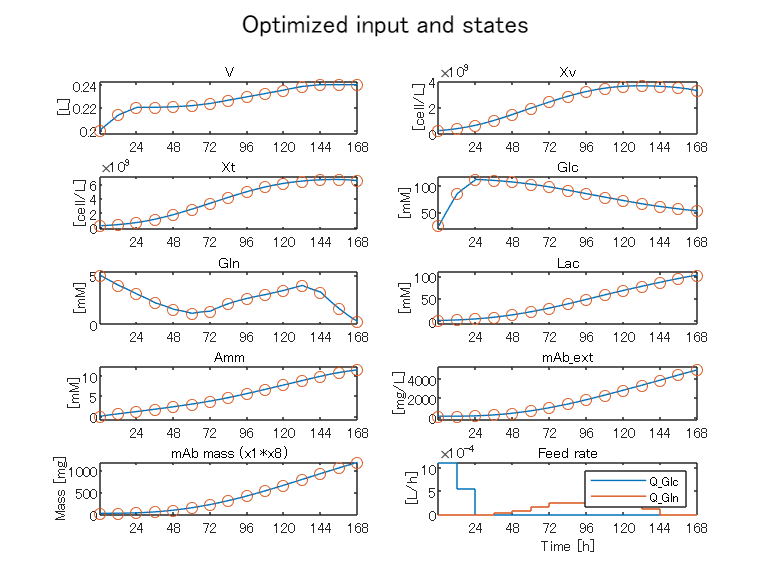

simTrueMFModel(Info_true,Ts,x0);

## Plant-model mismatch disturbs off-line optimization

Specify the model with intentionally errored parameter values to a new nlmpc object.

nlmpcMFTrue_error = nlmpcMFTrue;
STATEFCN = @multiFeedStateFcnError;
nlmpcMFTrue_error.Model.StateFcn = @(x,u) discretizeStateFcn(x,u,Ts,STATEFCN);
nlmpcMFTrue_error.Optimization.CustomCostFcn = @(X,U,e,data) 1/(X(end,8)*X(end,1)) + rho_e*e^2;
validateFcns(nlmpcMFTrue_error, x0, u0);

Model.StateFcn is OK.
Model.OutputFcn is OK.
Optimization.CustomCostFcn is OK.
ユーザー指定のモデル、コストおよび制約関数の解析が完了しました。


Start optimization.

timenow = datestr(datetime('now'));
fprintf('Optimization started at %s',timenow);

Optimization started at 05-Dec-2022 23:38:33

tic
[~,~,Info_true_error] = nlmpcmove(nlmpcMFTrue_error,x0,u0,[],[],options)

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           1    5.000000e-02     2.216e+00     1.000e+00     0.000e+00     2.000e+00  
    1           3    8.837727e-03     7.473e-01     1.000e+00     3.255e+01     3.604e+03  
    2           5    6.256014e-03     3.600e-01     1.000e+00     9.042e+00     4.774e+01  
    3           7    7.036875e-03     7.000e-03     1.000e+00     1.741e+00     1.515e+01  
    4           9    7.042255e-03     1.673e-06     1.000e+00     2.061e-02     6.740e-02  
    5          11    7.042159e-03     8.741e-10     1.000e+00     3.445e-04     1.094e-02  
    6          13    7.041678e-03     4.214e-09     1.000e+00     1.725e-03     1.094e-02  
    7          15    7.039273e-03     1.719e-08     1.000e+00     8.623e-03     1.094e-02  
    8          17    7.027276e-03     1.856e-07     1.000e+00     4.309e-02     1.

Info_true_error = フィールドをもつ struct :
         MVopt: [15×2 double]
          Xopt: [15×18 double]
          Yopt: [15×18 double]
          Topt: [15×1 double]
         Slack: 0.1786
      ExitFlag: 1
    Iterations: 194
          Cost: 0.0016


toc

経過時間は 57.428968 秒です。


printFinalmAb(Info_true_error);

Final liquid volume: 0.240143 L
Final mAb conc: 2663.47 mg/L
Final mAb amount: 639.613 mg


Simulate the true model with the feeding trajectory optimized in the presense of parameter errors.

Final liquid volume: 0.240143 L
Final mAb conc: 3948.13 mg/L
Final mAb amount: 948.115 mg


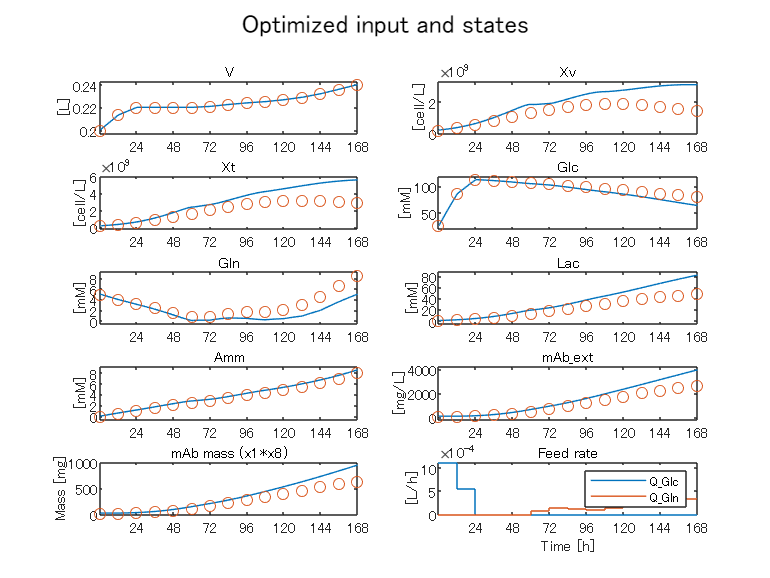

simTrueMFModel(Info_true_error,Ts,x0);

## Design nonlinear MPC with the reduced model

Create a nonlinear MPC object with 10 states, 10 outputs, 2 manipulated variables, and NO measured disturbance.

**State variables**

- `x1 = V [L]`: liquid volume in the reactor

- `x2 = Xv [cell/L]`: viable cell density

- `x3 = Xt [cell/L]`: total cell density 

- `x4 = Gl`c` [mM]`: Glucose concentration

- `x5 = Gln [mM]`: Glutamine concentration

- `x6 = Lac [mM]`: Lactate concentration

- `x7 = Amm [mM]`: Ammonia concentration

- `x8 = mAb_ext [mg/L]`: extracellular mAb concentration

- `x9 = V_Glc [L]`: fed volume of glucose feed medium 

- `x10 = V_Gln [L]`: fed volume of glutamine feed medium 

nlmpcMFReduced = nlmpc(10,10,2); % nlpmc object

標準のコスト関数では、MV が OV より少ないため、既定で 1 つ以上の OV に 0 の重みが割り当てられます。


Given the expected bioprocess duration `Tf`, choose the controller sample time `Ts` and prediction horizon.

Tf = 168;   % [h] bioprocess duration
Ts = 12;    % [h] prediction model sample time
N = Tf/Ts;  % [step] prediction horizon
nlmpcMFReduced.Ts = Ts;
nlmpcMFReduced.PredictionHorizon = N;
% nlmpcobj.ControlHorizon = N;
nlmpcMFReduced.ControlHorizon = (24/Ts)*ones(7,1);
nlmpcMFReduced.Optimization.MVInterpolationOrder = 1;

### Specify the state function in the controller

The function converts the continuous-time model to discrete time using a multi-step Forward Euler integration formula.

STATEFCN = @multiFeedRStateFcn;
nlmpcMFReduced.Model.StateFcn = @(x,u) discretizeStateFcn(x,u,Ts,STATEFCN);
nlmpcMFReduced.Model.OutputFcn = @(x,u) x;

% the nonlinear state function is for discrete-time models.
nlmpcMFReduced.Model.IsContinuousTime = false;

### Specify the bounds for input/output variables

% states
stateName = {'V','Xv','Xt','Glc','Gln','Lac','Amm','mAb_ext', ...
                'V_Glc', 'V_Gln',...
            };
stateUnit = {'L', 'cell/L', 'cell/L', 'mM', 'mM', 'mM', 'mM', 'mg/L', ...
                'L', 'L' ...
            };
stateScaleFactor = [0.04 2.5E+9 2.5E+9 25 5 25 5 4000 0.02 0.02];

for stateIdx = 1:10
    nlmpcMFReduced.States(stateIdx).Name = stateName{stateIdx};
    nlmpcMFReduced.States(stateIdx).ScaleFactor = stateScaleFactor(stateIdx);
    nlmpcMFReduced.States(stateIdx).Units = stateUnit{stateIdx};
end

% manipulated variable
nlmpcMFReduced.MV(1).Name = 'Q_Glc';
nlmpcMFReduced.MV(1).ScaleFactor = 0.02/168;
nlmpcMFReduced.MV(1).Units = 'L/h';
nlmpcMFReduced.MV(1).Min = 0;
nlmpcMFReduced.MV(1).MinECR = 0;

nlmpcMFReducede.MV(2).Name = 'Q_Gln';
nlmpcMFReduced.MV(2).ScaleFactor = 0.02/168;
nlmpcMFReduced.MV(2).Units = 'L/h';
nlmpcMFReduced.MV(2).Min = 0;
nlmpcMFReduced.MV(2).MinECR = 0;

% output variables
for outputIdx = 1:10
    nlmpcMFReduced.OV(outputIdx).Name = nlmpcMFReduced.States(outputIdx).Name;
    nlmpcMFReduced.OV(outputIdx).ScaleFactor = nlmpcMFReduced.States(outputIdx).ScaleFactor;
    nlmpcMFReduced.OV(outputIdx).Units = nlmpcMFReduced.States(outputIdx).Units;
end

% Total feed limit
nlmpcMFReduced.OV(9).Max = 0.02;
nlmpcMFReduced.OV(9).MaxECR = 0.02;  % 0.02
nlmpcMFReduced.OV(10).Max = 0.02;
nlmpcMFReduced.OV(10).MaxECR = 0.02;  % 0.02

% weight for the slack variable e
rho_e = 1E-5; % 1E-5

### Specify the custom cost function

nlmpcMFReduced.Optimization.CustomCostFcn = @(X,U,e,data) 1/(X(end,8)*X(end,1)) + rho_e*e^2;
nlmpcMFReduced.Optimization.ReplaceStandardCost = true;

### Specify the solver option

nlmpcMFReduced.Optimization.SolverOptions.Display = 'iter-detailed';

### Validate the nlmpc object

validateFcns(nlmpcMFReduced, [x0(1:8);0;0], u0);

Model.StateFcn is OK.
Model.OutputFcn is OK.
Optimization.CustomCostFcn is OK.
ユーザー指定のモデル、コストおよび制約関数の解析が完了しました。


Start optimization.

timenow = datestr(datetime('now'));
fprintf('Optimization started at %s',timenow);

Optimization started at 05-Dec-2022 23:39:33

tic
[~,~,Info_reduced] = nlmpcmove(nlmpcMFReduced,[x0(1:8);0;0],u0,[],[],options)

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           1    5.000000e-02     2.396e-01     1.000e+00     0.000e+00     2.000e+00  
    1           4    1.729522e-02     3.250e-01     1.000e+00     4.734e+01     1.026e+04  
    2           6    1.442285e-02     1.021e-01     1.000e+00     7.615e+00     4.371e+01  
    3           8    1.455307e-02     6.154e-04     1.000e+00     4.938e-01     2.208e+00  
    4          10    1.455221e-02     4.682e-09     1.000e+00     2.861e-03     4.602e-02  
    5          12    1.454943e-02     3.505e-09     1.000e+00     4.131e-03     5.090e-02  
    6          14    1.453551e-02     1.310e-08     1.000e+00     2.065e-02     5.089e-02  
    7          16    1.446609e-02     7.785e-08     1.000e+00     1.032e-01     5.076e-02  
    8          18    1.412312e-02     2.967e-06     1.000e+00     5.145e-01     5.

Info_reduced = フィールドをもつ struct :
         MVopt: [15×2 double]
          Xopt: [15×10 double]
          Yopt: [15×10 double]
          Topt: [15×1 double]
         Slack: 0.1157
      ExitFlag: 1
    Iterations: 203
          Cost: 8.7742e-04


toc

経過時間は 21.349858 秒です。


printFinalmAb(Info_reduced);

Final liquid volume: 0.240093 L
Final mAb conc: 4747.69 mg/L
Final mAb amount: 1139.89 mg


Final liquid volume: 0.240093 L
Final mAb conc: 4902.88 mg/L
Final mAb amount: 1177.15 mg


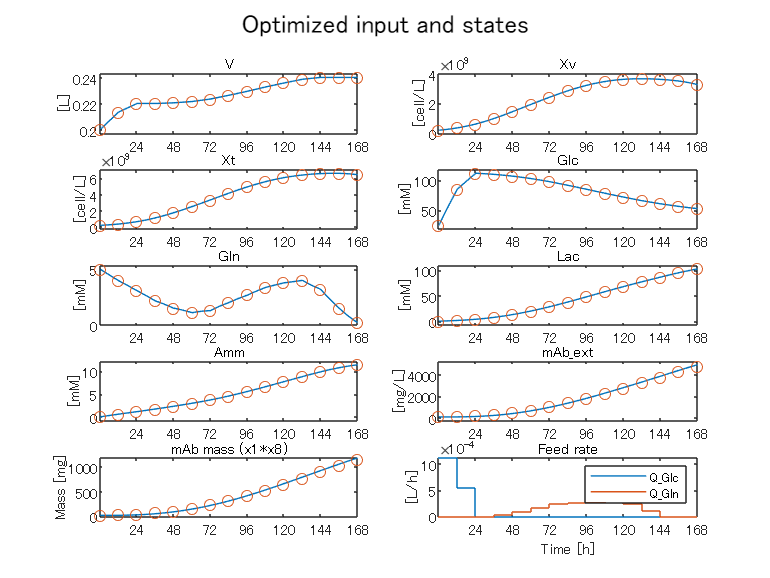

simTrueMFModel(Info_reduced,Ts,x0);

## Plant-model mismatch disturbs off-line optimization

nlmpcMFReduced_error = nlmpcMFReduced;
STATEFCN = @multiFeedRStateFcnError;
nlmpcMFReduced_error.Model.StateFcn = @(x,u) discretizeStateFcn(x,u,Ts,STATEFCN);
nlmpcMFReduced_error.Model.OutputFcn = @(x,u) x;
% nlmpcMFReduced_error.Optimization.CustomCostFcn = @(X,U,e,data) 1/(X(end,8)*X(end,1)) + rho_e*e^2; % mAb*V [mg]
validateFcns(nlmpcMFReduced_error, [x0(1:8);0;0], u0);

Model.StateFcn is OK.
Model.OutputFcn is OK.
Optimization.CustomCostFcn is OK.
ユーザー指定のモデル、コストおよび制約関数の解析が完了しました。


Start optimization.

timenow = datestr(datetime('now'));
fprintf('Optimization started at %s',timenow);

Optimization started at 05-Dec-2022 23:40:14

tic
[~,~,Info_reduced_error] = nlmpcmove(nlmpcMFReduced_error,[x0(1:8);0;0],u0,[],[],options)

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           1    5.000000e-02     2.437e-01     1.000e+00     0.000e+00     2.000e+00  
    1           3    4.539235e-03     7.613e-01     1.000e+00     2.599e+01     3.602e+03  
    2           5    5.811984e-03     4.033e-01     1.000e+00     8.026e+00     1.756e+01  
    3           7    6.469390e-03     5.735e-04     1.000e+00     9.143e-01     5.415e+00  
    4           9    6.472441e-03     1.557e-08     1.000e+00     2.275e-03     1.481e-02  
    5          11    6.472346e-03     8.569e-10     1.000e+00     3.834e-04     1.175e-02  
    6          13    6.471873e-03     4.108e-09     1.000e+00     1.917e-03     1.174e-02  
    7          15    6.469505e-03     1.613e-08     1.000e+00     9.584e-03     1.174e-02  
    8          17    6.457701e-03     1.680e-07     1.000e+00     4.789e-02     1.

Info_reduced_error = フィールドをもつ struct :
         MVopt: [15×2 double]
          Xopt: [15×10 double]
          Yopt: [15×10 double]
          Topt: [15×1 double]
         Slack: 0.1766
      ExitFlag: 1
    Iterations: 196
          Cost: 0.0016


toc

経過時間は 20.663851 秒です。


printFinalmAb(Info_reduced_error);

Final liquid volume: 0.240141 L
Final mAb conc: 2611.16 mg/L
Final mAb amount: 627.048 mg


Final liquid volume: 0.240141 L
Final mAb conc: 3948.13 mg/L
Final mAb amount: 948.11 mg


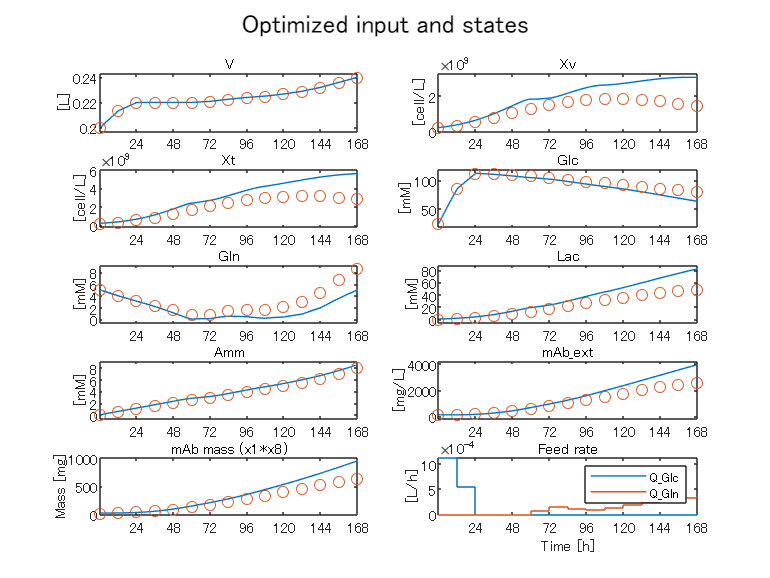

simTrueMFModel(Info_reduced_error,Ts,x0);

## On-line reoptimization in the presence of the plant-model mismatch

nlmpcMFReduced_error.Model.StateFcn = @(x,u,N) discretizeStateFcn(x,u,Ts,STATEFCN);
nlmpcMFReduced_error.Model.NumberOfParameters = 1;
nlmpcMFReduced_error.Model.OutputFcn = @(x,u,N) x;
nlmpcMFReduced_error.Optimization.CustomCostFcn = @(X,U,e,data,N) 1/(X(1+N,8)*X(1+N,1)) + rho_e*e^2; % mAb*V [mg]
validateFcns(nlmpcMFReduced_error, [x0(1:8);0;0], u0, [], {N});

Model.StateFcn is OK.
Model.OutputFcn is OK.
Optimization.CustomCostFcn is OK.
ユーザー指定のモデル、コストおよび制約関数の解析が完了しました。


Open the Simulink model.

mdl = 'MPCMultiFeed_reduced';
open_system(mdl)

To use the optional parameter in the prediction model, the model has a Simulink Bus block connected to the `params` input port of the Nonlinear MPC Controller block. To configure this bus block to use the `N` parameter, create a Bus object in the MATLAB workspace, and configure the Bus Creator block to use this object. Name the Bus object `'myBusObject'`.

createParameterBus(nlmpcMFReduced_error,[mdl '/Nonlinear MPC'],'myBusObject',{N});

Simulink バス オブジェクト "myBusObject" が MATLAB ワークスペースで作成され、Bus Creator ブロック "MPCMultiFeed_reduced/Nonlinear MPC" がこのオブジェクトを使用するように構成されています。


Start simulation.

timenow = datestr(datetime('now'));
fprintf('Optimization started at %s',timenow);

Optimization started at 05-Dec-2022 23:40:39

tic
simout = sim(mdl);

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           1    5.000000e-02     1.464e-01     1.000e+00     0.000e+00     2.000e+00  
    1           4    3.568659e-03     7.193e-01     1.000e+00     1.252e+01     4.883e+02  
    2           6    4.206350e-03     3.896e-03     1.000e+00     2.198e+00     7.859e-01  
    3           8    4.271130e-03     1.766e-05     1.000e+00     6.154e-02     3.256e-01  
    4          10    4.271226e-03     6.513e-10     1.000e+00     1.516e-04     3.735e-03  
    5          12    4.271168e-03     1.894e-09     1.000e+00     3.081e-04     3.866e-03  
    6          14    4.270879e-03     9.383e-09     1.000e+00     1.541e-03     3.866e-03  
    7          16    4.269434e-03     4.470e-08     1.000e+00     7.701e-03     3.866e-03  
    8          18    4.262236e-03     4.363e-07     1.000e+00     3.847e-02     3.

toc

経過時間は 74.481865 秒です。


Final liquid volume: 0.239728 L
Final mAb conc: 4848.67 mg/L
Final mAb amount: 1162.36 mg


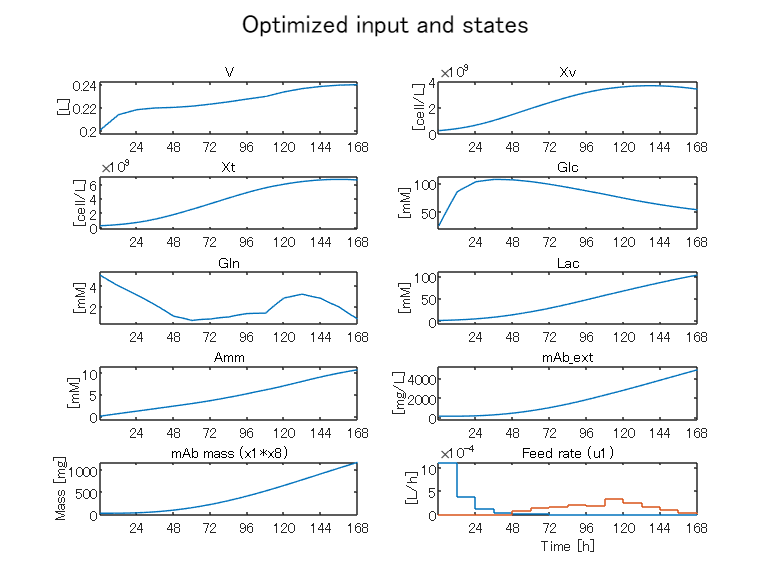

plotSimulinkLog(simout);